%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% MAIN.M
%
% Este script realiza as seguintes tarefas:
%  1) Cria uma tabela de metadados para os áudios e importa os sinais.
%  2) Realiza pré-processamento dos sinais (remoção de silêncio inicial,
%     normalização, sem ajuste de duração para features).
%  3) Representa graficamente os sinais brutos para dígitos 0-9, repetição 5.
%  4) Extrai 5 características temporais de cada sinal antes de padding.
%  5) Representa graficamente os sinais pré-processados para dígitos 0-9, repetição 5.
%  6) Compara visualmente os gráficos de 3 e 5 (descrito no texto).
%  7) Visualiza as features e identifica as melhores para discriminação.
%  8) Remove os sinais de áudio da tabela e salva em finalData.mat.
%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

clear; close all; clc;

%% PARÂMETROS INICIAIS
baseDir      = './data/40';    % Pasta onde estão os ficheiros .wav
participant  = 40;           % ID do participante
digitsRange  = 0:9;          % Dígitos de 0 a 9
repetitions  = 0:49;         % 50 gravações de cada dígito
nDigits      = length(digitsRange);
nReps        = length(repetitions);

%% PONTO 1 e 2: CRIAR ESTRUTURA (TABELA) E IMPORTAR SINAIS
nTotal = nDigits * nReps;
diretorio       = cell(nTotal,1);
nomeFicheiro    = cell(nTotal,1);
participanteVec = zeros(nTotal,1);
digito          = zeros(nTotal,1);
repeticao       = zeros(nTotal,1);
audioSignal     = cell(nTotal,1);
fsVal           = zeros(nTotal,1);

idx = 1;
for d = digitsRange
    for r = repetitions
        nomeArq = sprintf('%d_%d_%d.wav', d, participant, r);
        caminho = fullfile(baseDir, nomeArq);

        diretorio{idx}    = caminho;
        nomeFicheiro{idx} = nomeArq;
        participanteVec(idx) = participant;
        digito(idx)       = d;
        repeticao(idx)    = r;

        try
            [sig, fs] = audioread(caminho);
        catch ME
            warning('Erro ao ler %s: %s', caminho, ME.message);
            sig = []; fs = NaN;
        end

        audioSignal{idx} = sig;
        fsVal(idx)       = fs;

        idx = idx + 1;
    end
end

T = table(diretorio, nomeFicheiro, participanteVec, digito, repeticao, ...
          audioSignal, fsVal, ...
    'VariableNames', {'Diretorio','NomeFicheiro','Participante','Digito',...
                      'Repeticao','AudioSignal','Fs'});

disp('--- Tabela com Metadados e Sinais (primeiras 10 linhas) ---');

--- Tabela com Metadados e Sinais (primeiras 10 linhas) ---


disp(T(1:min(500,height(T)), :));

            Diretorio             NomeFicheiro      Participante    Digito    Repeticao      AudioSignal        Fs  
    _________________________    _______________    ____________    ______    _________    ________________    _____

    {'./data/40/0_40_0.wav' }    {'0_40_0.wav' }         40           0           0        {36309×1 double}    48000
    {'./data/40/0_40_1.wav' }    {'0_40_1.wav' }         40           0           1        {38165×1 double}    48000
    {'./data/40/0_40_2.wav' }    {'0_40_2.wav' }         40           0           2        {34469×1 double}    48000
    {'./data/40/0_40_3.wav' }    {'0_40_3.wav' }         40           0           3        {34906×1 double}    48000
    {'./data/40/0_40_4.wav' }    {'0_40_4.wav' }         40

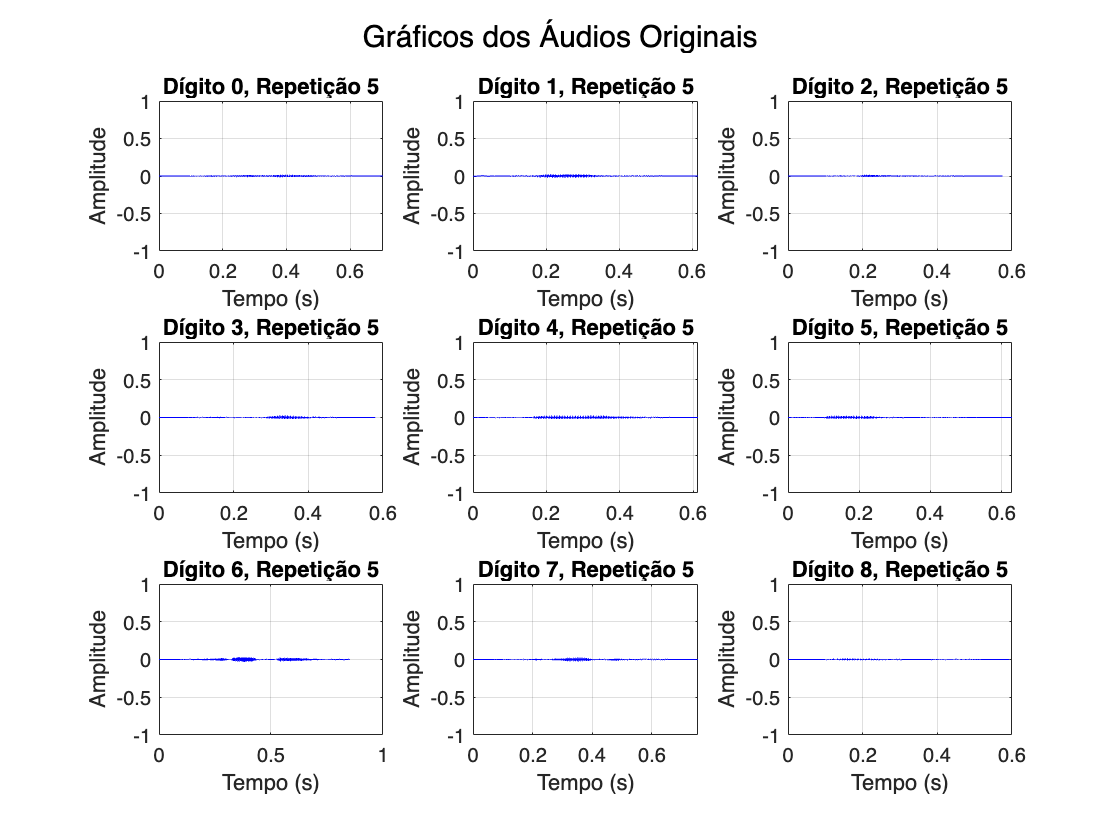


%% PONTO 3: REPRESENTAR GRAFICAMENTE OS SINAIS BRUTOS (DIGITOS 0-9, REPETIÇÃO 5)
figure('Name','Gráficos dos Áudios Originais','NumberTitle','off');
for d = 0:8  % Plot digits 0-8 to match Figure 2 (3x3 grid)
    subplot(3,3,d+1);
    idx = find(T.Digito == d & T.Repeticao == 5, 1);
    if ~isempty(idx) && ~isempty(T.AudioSignal{idx})
        sig = T.AudioSignal{idx};
        fs = T.Fs(idx);
        t = (0:length(sig)-1)/fs;
        plot(t, sig, 'b');
        xlabel('Tempo (s)');
        ylabel('Amplitude');
        title(sprintf('Dígito %d, Repetição 5', d));
        ylim([-1 1]);  % Match Figure 2 amplitude range
        grid on;
    else
        title(sprintf('Dígito %d (não encontrado)', d));
    end
end
sgtitle('Gráficos dos Áudios Originais');

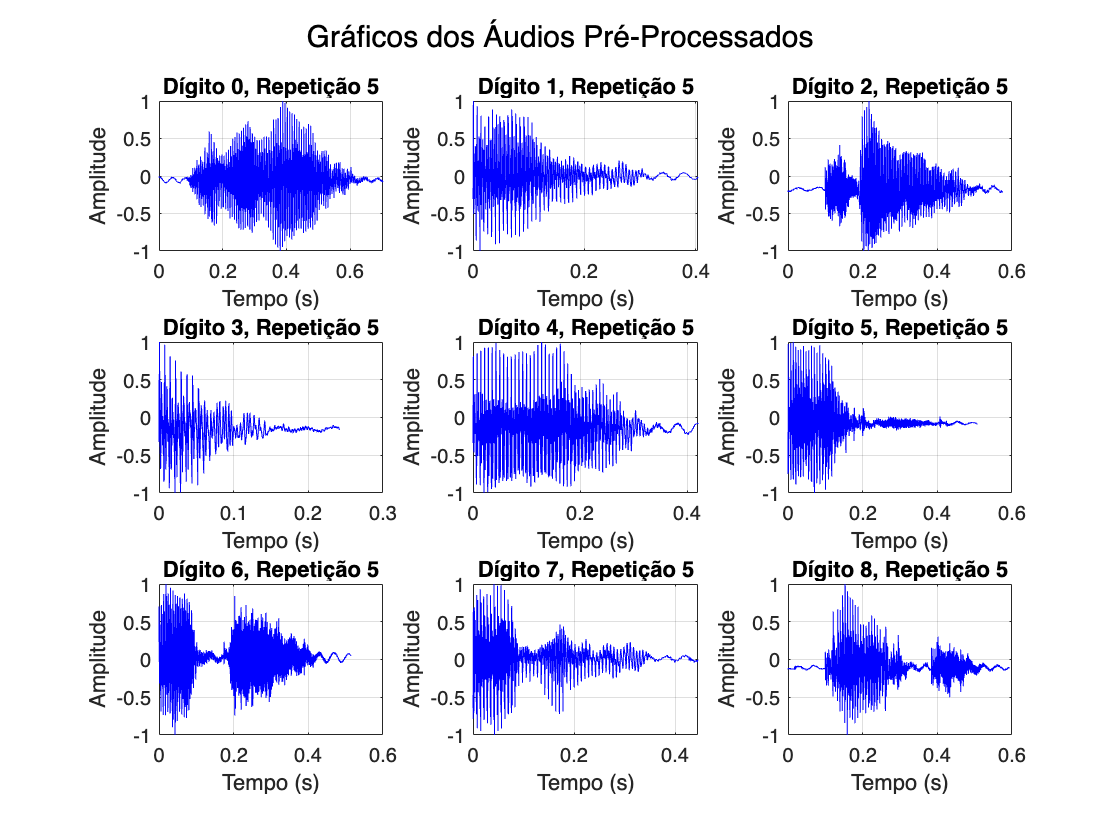


%% PONTO 4: PRÉ-PROCESSAMENTO DOS SINAIS
% Passos: 1) Remoção de silêncio inicial
%         2) Normalização para [-1, 1]
%         (Sem padding, pois não é necessário para features ou plots)
preprocSignals = cell(nTotal,1);

for i = 1:nTotal
    if ~isempty(T.AudioSignal{i})
        ppSig = preprocessSignal(T.AudioSignal{i}, T.Fs(i));
    else
        ppSig = [];
    end
    preprocSignals{i} = ppSig;
end

T.PreprocSignal = preprocSignals;

%% PONTO 5: REPRESENTAR GRAFICAMENTE OS SINAIS PRÉ-PROCESSADOS (DIGITOS 0-9, REPETIÇÃO 5)
figure('Name','Gráficos dos Áudios Pré-Processados','NumberTitle','off');
for d = 0:8  % Plot digits 0-8 to match Figure 2 style
    subplot(3,3,d+1);
    idx = find(T.Digito == d & T.Repeticao == 5, 1);
    if ~isempty(idx) && ~isempty(T.PreprocSignal{idx})
        sig = T.PreprocSignal{idx};
        fs = T.Fs(idx);
        t = (0:length(sig)-1)/fs;
        plot(t, sig, 'b');
        xlabel('Tempo (s)');
        ylabel('Amplitude');
        title(sprintf('Dígito %d, Repetição 5', d));
        ylim([-1 1]);  % Normalized amplitude
        grid on;
    else
        title(sprintf('Dígito %d (não encontrado)', d));
    end
end
sgtitle('Gráficos dos Áudios Pré-Processados');

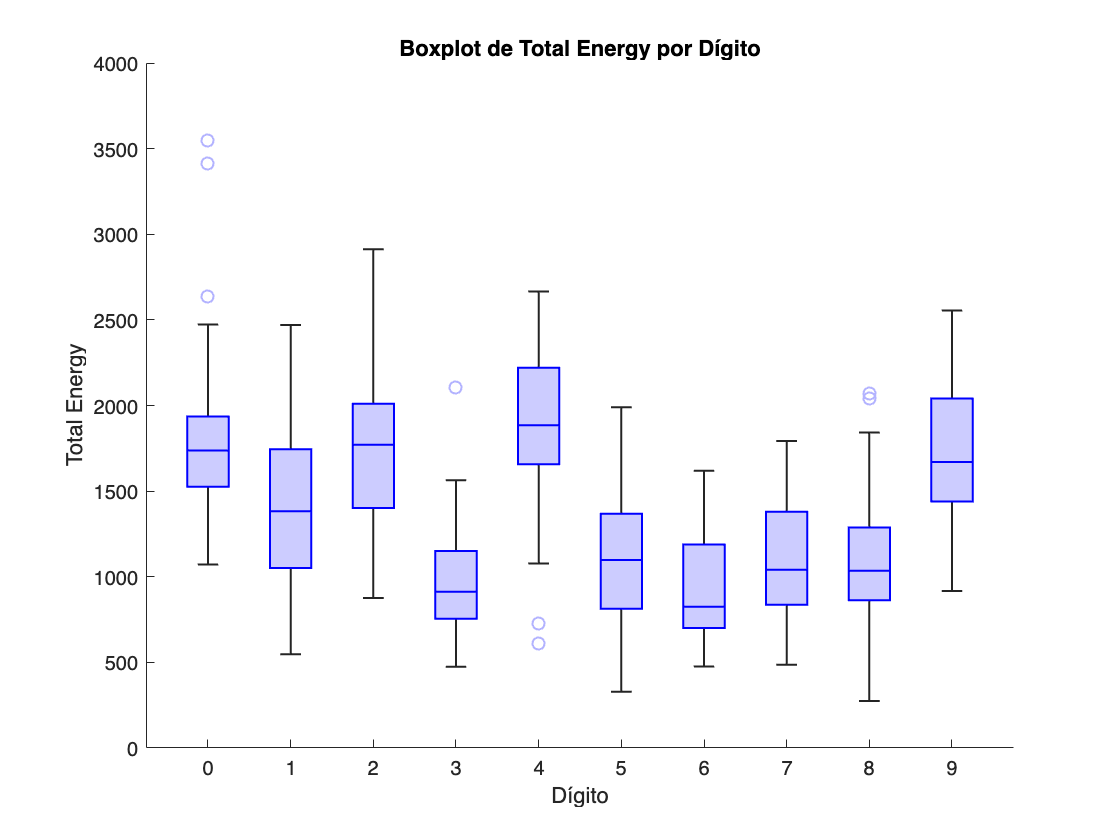


%% PONTO 6: COMPARAÇÃO VISUAL DOS GRÁFICOS (DESCRIÇÃO NO TEXTO ABAIXO)

%% PONTO 7: CÁLCULO DAS FEATURES
% Features: 1) Energia total, 2) Desvio padrão, 3) Amplitude máxima,
%           4) Zero Crossing Rate, 5) Duração (s)
nFeatures = 5;
featuresMatrix = zeros(nTotal, nFeatures);

for i = 1:nTotal
    if ~isempty(T.PreprocSignal{i})
        feats = computeFeatures(T.PreprocSignal{i}, T.Fs(i));
    else
        feats = zeros(1, nFeatures);
    end
    featuresMatrix(i,:) = feats;
end

T.TotalEnergy = featuresMatrix(:,1);
T.StdDev      = featuresMatrix(:,2);
T.MaxAmp      = featuresMatrix(:,3);
T.ZCR         = featuresMatrix(:,4);
T.Duration    = featuresMatrix(:,5);

%% PONTO 8: VISUALIZAÇÃO DAS FEATURES
% A) Boxplot de Total Energy
figure('Name','Boxplot das Características Extraídas','NumberTitle','off');
boxchart(categorical(T.Digito), T.TotalEnergy, 'BoxFaceColor', 'b', 'MarkerColor', [0.7 0.7 1]);
xlabel('Dígito');
ylabel('Total Energy');
title('Boxplot de Total Energy por Dígito');

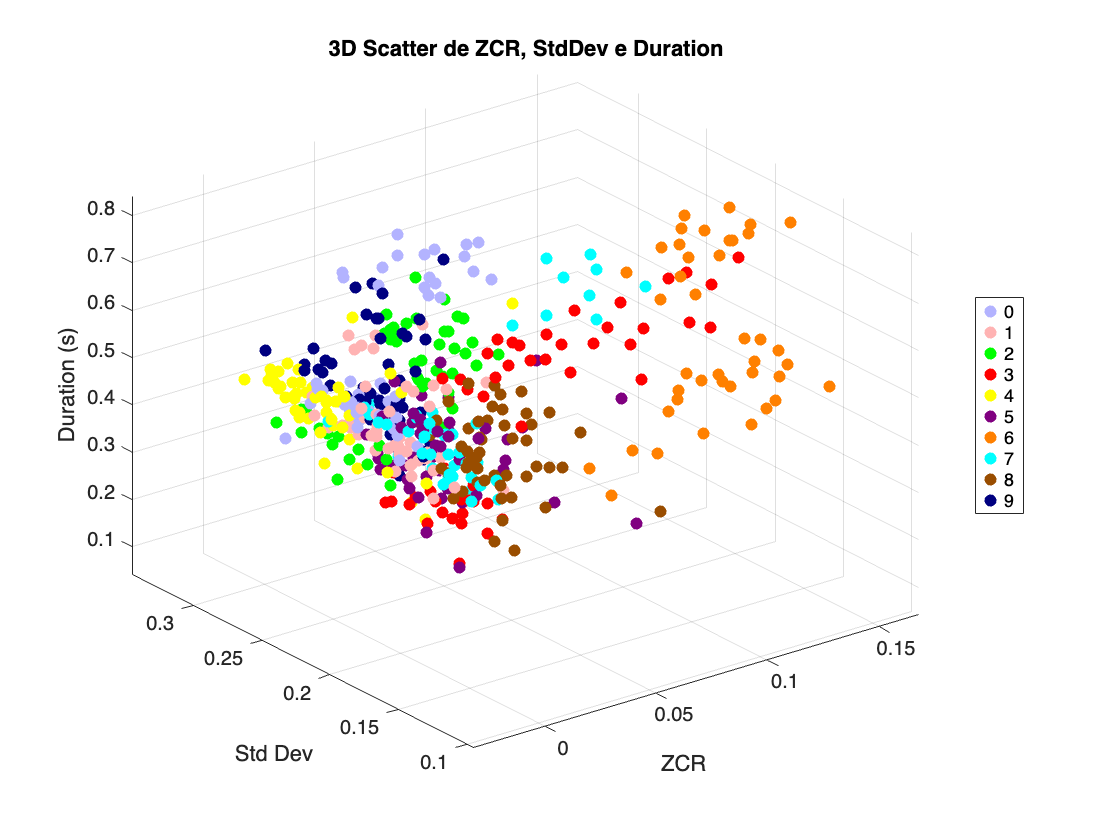


% B) 3D Scatter de ZCR, StdDev, Duration em uma janela separada
figure('Name','3D Scatter de Características','NumberTitle','off');
hold on;
colors = [0.7 0.7 1; 1 0.7 0.7; 0 1 0; 1 0 0; 1 1 0; 0.5 0 0.5; 1 0.5 0; 0 1 1; 0.6 0.3 0; 0 0 0.5];
for d = 0:9
    idx = T.Digito == d;
    scatter3(T.ZCR(idx), T.StdDev(idx), T.Duration(idx), 36, colors(d+1,:), 'filled');
end
hold off;
xlabel('ZCR');
ylabel('Std Dev');
zlabel('Duration (s)');
title('3D Scatter de ZCR, StdDev e Duration');
legend(cellstr(num2str((0:9)')), 'Location', 'eastoutside');
view(3);         % Força a visualização em 3D
grid on;         % Adiciona grade para melhor visualização
rotate3d on;     % Habilita a rotação interativa

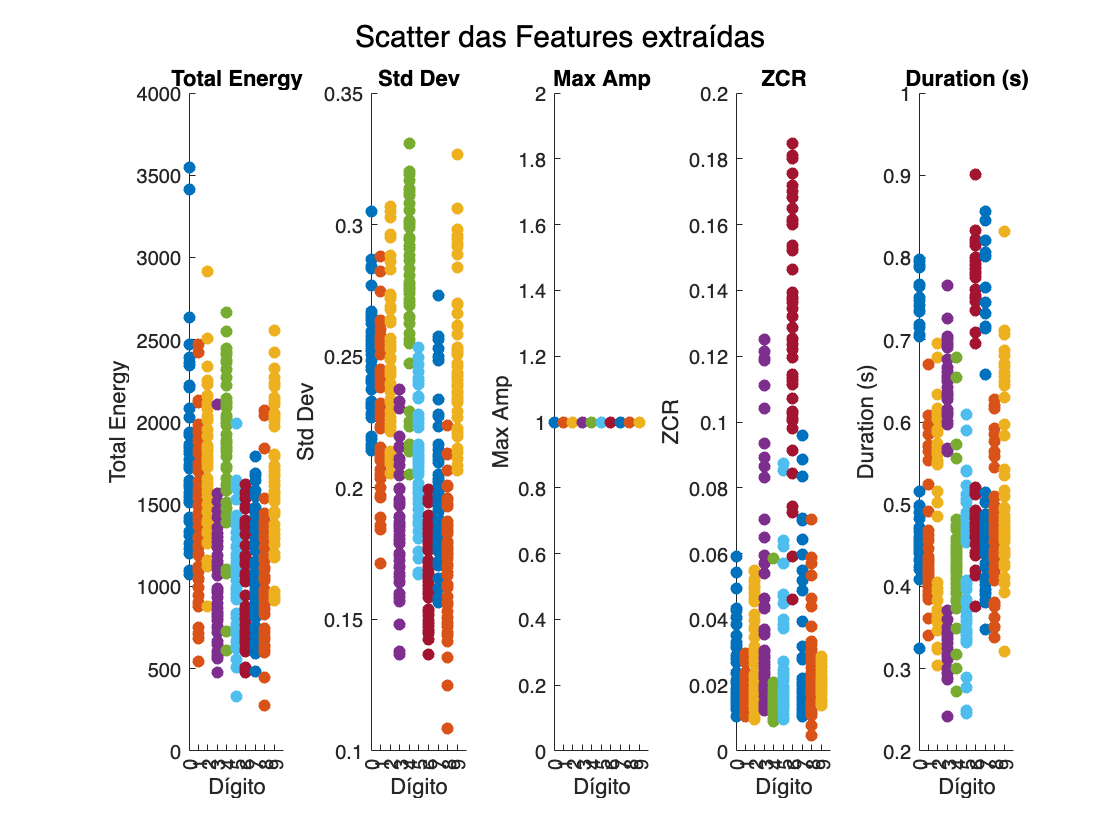



% B) Scatter e Boxplots para todas as features (original)
figure('Name','Scatter das 5 Features','NumberTitle','off');
featureNames = {'Total Energy','Std Dev','Max Amp','ZCR','Duration (s)'};
for f = 1:nFeatures
    subplot(1,nFeatures,f);
    hold on;
    for d = digitsRange
        idxD = (T.Digito == d);
        scatter(repmat(d,1,sum(idxD)), featuresMatrix(idxD,f), 'filled');
    end
    hold off;
    xlabel('Dígito');
    ylabel(featureNames{f});
    xticks(digitsRange);
    title(featureNames{f});
end
sgtitle('Scatter das Features extraídas');

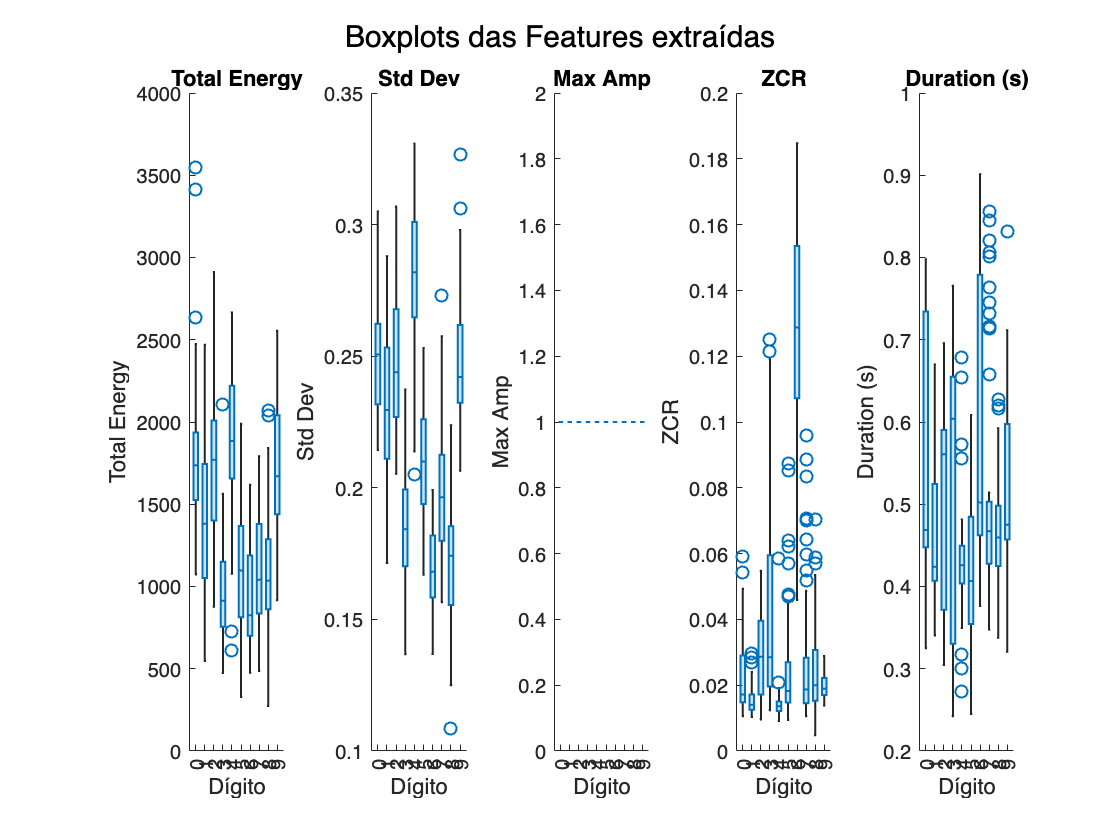


figure('Name','Boxplots das 5 Features','NumberTitle','off');
for f = 1:nFeatures
    subplot(1,nFeatures,f);
    boxchart(categorical(T.Digito), featuresMatrix(:,f));
    xlabel('Dígito');
    ylabel(featureNames{f});
    title(featureNames{f});
end
sgtitle('Boxplots das Features extraídas');


%% PONTO 9: REMOÇÃO DOS SINAIS E SALVAMENTO
T.AudioSignal   = [];
T.PreprocSignal = [];
save('finalData.mat', 'T');

disp('--- Fim: Estrutura de dados salva em finalData.mat ---');

--- Fim: Estrutura de dados salva em finalData.mat ---



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% FUNÇÕES AUXILIARES
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function [ppSig] = preprocessSignal(sig, fs)
    frameSizeSec = 0.001;
    frameSamples = round(frameSizeSec * fs);
    numFrames    = floor(length(sig) / frameSamples);
    energy       = getFrameEnergy(sig, frameSamples, numFrames);

    energyThreshold = 0.01;
    startFrame = find(energy > energyThreshold, 1);
    if isempty(startFrame)
        startFrame = 1;
    end
    startSample = (startFrame - 1)*frameSamples + 1;

    ppSig = sig(startSample:end);

    minVal = min(ppSig);
    maxVal = max(ppSig);
    if (maxVal - minVal) < 1e-12
        ppSig = zeros(size(ppSig));
    else
        ppSig = (ppSig - minVal) / (maxVal - minVal);  % [0, 1]
        ppSig = 2*ppSig - 1;                           % [-1, 1]
    end
end

function energyVec = getFrameEnergy(y, frameSamples, numFrames)
    energyVec = zeros(numFrames, 1);
    for j = 1:numFrames
        frame = y((j-1)*frameSamples + 1 : j*frameSamples);
        energyVec(j) = sum(frame.^2);
    end
end

function feats = computeFeatures(sig, fs)
    feats = zeros(1,5);
    feats(1) = sum(sig.^2);            % Energia total
    feats(2) = std(sig);               % Desvio padrão
    feats(3) = max(abs(sig));          % Amplitude máxima
    feats(4) = zerocrossrate(sig);     % Zero Crossing Rate
    feats(5) = length(sig)/fs;         % Duração em segundos
end

function zcr = zerocrossrate(sig)
    s  = sign(sig);
    ds = diff(s);
    zcr = sum(ds ~= 0) / (length(sig)-1);
end